# Transitioning From Statistical to Physics Based Radar Models

A radar is a perception system that uses an antenna or antenna array to capture RF energy, which is then down converted and processed to provide information on objects in the radar's field of view. The received signal needs to pass through both a signal processing subsystem and a data processing subsystem.

The goal of the signal processing subsystem is to translate received IQ signals to target detections. The data processing subsystem takes these detections and produces tracks corresponding to the detected targets.

The signal processing subsystem helps to generate a snapshot of the scene at the current time and includes information on whether an object is in the coverage and if so, where it is. The data processing subsystem links those snapshots together so we can understand what happened over time. This helps to obtain Doppler information in addition to predictions of where targets are heading.

Radar engineers that simulate and model algorithms and systems need to work across a range of abstraction levels that span the signal and data processing domains. The level of abstraction depends on the phase of the radar development life cycle, the length of the scene being simulated, and the type of engineering work being performed.

At early stages of a project, as design trade-offs are being explored, modeling at the radar equation level may be adequate. As a project progresses, it will be necessary to increase the level of model fidelity, moving from a statistical level to signal level simulation. In addition, the length of a scenario can dictate which modeling abstraction level makes sense. For example, for longer scenario times (seconds, minutes, or longer), it may be better to generate statistical or probabilistic radar detections and tracks to cover a mission or to test tracking and sensor fusion algorithms. Alternatively, higher fidelity, physics-based simulations that include transmitted waveforms, signal propagation through the environment, reflections off targets, and received signals at a receive array are needed for events of interest or for when signal processing algorithms are being developed.

This example starts with a statistical model for a given scene and then the equivalent IQ signal level model is created programmatically from the statistical model.

In the first portion of the example, we will build a statistical model and generate detections based on the radar equation. In the second portion of the example, we create the equivalent IQ signal level model for the same scenario and compare the results. This workflow is a very convenient way to get a signal level model up and running quickly. Once the basic signal model is in place, it can be extended as the project dictates.

## Define the scene

To start, we define a scenario with fixed-location surveillance radar. There are three targets in the radar?s field of view. The plot below shows the locations of the radar and targets.

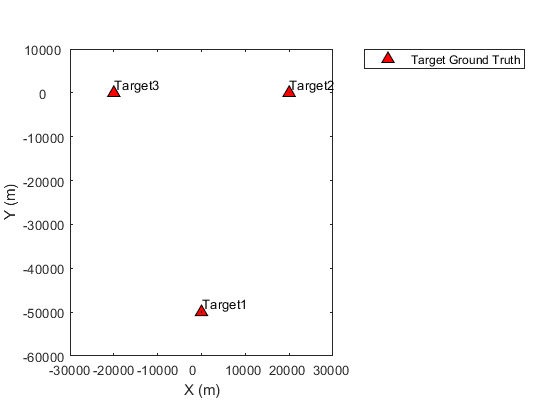

clear
% Create targets.

tgt1 = struct( ...
    'PlatformID', 1, ...
    'Position', [0 -50e3 -1e3], ...
    'Velocity', [0 900*1e3/3600 0]);

tgt2 = struct( ...
    'PlatformID', 2, ...
    'Position', [20e3 0 -500], ...
    'Velocity', [700*1e3/3600 0 0]);

tgt3 = struct( ...
    'PlatformID', 3, ...
    'Position', [-20e3 0 -500], ...
    'Velocity', [300*1e3/3600 0 0]);

tp = theaterPlot('XLim',[-30e3 30e3],'YLim',[-60e3 10e3],'ZLim',[-10e3 1e3]);
gtplot = platformPlotter(tp,'DisplayName','Target Ground Truth',...
    'Marker','^','MarkerSize',8,'MarkerFaceColor','r');
plotPlatform(gtplot,[tgt1.Position;tgt2.Position;tgt3.Position],...
    [tgt1.Velocity;tgt2.Velocity;tgt3.Velocity],{'Target1','Target2','Target3'});

## Define Radar for Detection Generation

Next, we define an airport surveillance radar that generates detections from a statistical model. The airport surveillance radar is installed 15 meters above the ground. The radar sensor definition includes the key radar parameters such as scanning type and field of view information.

The `radarDataGenerator` generated detections statistically based on the radar equation.

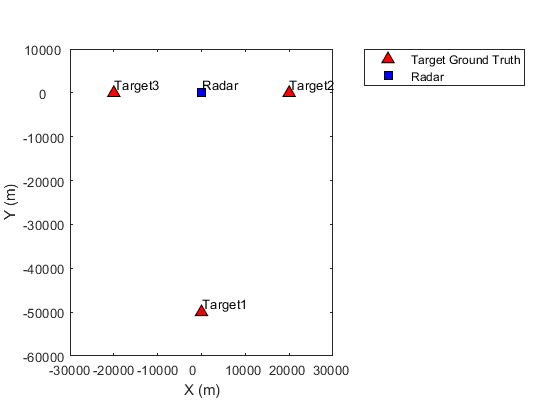


% Create an airport surveillance radar 15 meters above the ground
rpm = 12.5;
fov = [1.4;5]; % [azimuth; elevation]

scanrate = rpm*360/60;  % deg/s
updaterate = scanrate/fov(1); % Hz

sensor = radarDataGenerator(1, 'Rotator', ...
    'UpdateRate', updaterate, ...
    'MountingLocation', [0 0 -15], ...
    'MaxAzimuthScanRate', scanrate, ...
    'FieldOfView', fov, ...
    'AzimuthResolution', fov(1));

radarPosition = [0 0 0];
radarVelocity = [0 0 0];
radarplot = platformPlotter(tp,'DisplayName','Radar',...
    'Marker','s','MarkerSize',8,'MarkerFaceColor','b');
plotPlatform(radarplot,radarPosition,radarVelocity,{'Radar'})

## Generate Statistical Radar Detection 

The code below simulates a full scan of the surveillance radar. 

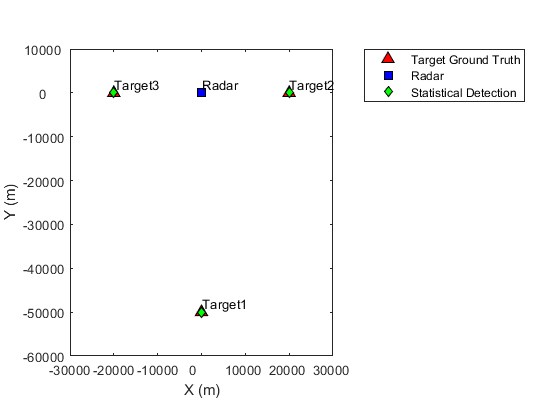

% Generate detections from a full scan of the radar
simTime = 0;
detBuffer = {};

rng(2020);
while true
    [dets, numDets, config] = sensor([tgt1 tgt2 tgt3], simTime);
    detBuffer = [detBuffer;dets]; %#ok<AGROW>

    % Is full scan complete?
    if config.IsScanDone
        break % yes
    end
    simTime = simTime+1/sensor.UpdateRate;
end

stadetpos = zeros(numel(detBuffer),3);
for m = 1:numel(detBuffer)
    stadetpos(m,:) = detBuffer{m}.Measurement.';
end
stadet = detectionPlotter(tp,'DisplayName','Statistical Detection',...
    'Marker','d','MarkerSize',6,'MarkerFaceColor','g');
plotDetection(stadet,stadetpos)

From the figure above, you can see the detections generated match the ground truth target locations. The three targets all indicated by a truth marker have a detection that is shown as an overlay on the truth marker.

## Define Radar for IQ Signal Generation and Processing

Next, assuming we are satisfied with the statistical level simulation, we would like to transition into IQ signal simulation so we can verify if our signal processing algorithms are working properly. Using the following command, we can easily create a radar transceiver  that produces the IQ signal based on the statistical sensor we configured earlier. 

sensor_iq = radarTransceiver(sensor)

sensor_iq =   radarTransceiver with properties:

                      Waveform: [1×1 phased.RectangularWaveform]
                   Transmitter: [1×1 phased.Transmitter]
               TransmitAntenna: [1×1 phased.Radiator]
                ReceiveAntenna: [1×1 phased.Collector]
                      Receiver: [1×1 phased.ReceiverPreamp]
            MechanicalScanMode: 'Circular'
    InitialMechanicalScanAngle: -0.10
            MechanicalScanRate: 75.00
            ElectronicScanMode: 'None'
              MountingLocation: [0 0 -15.00]
                MountingAngles: [0 0 0]
          NumRepetitionsSource: 'Property'
                NumRepetitions: 1.00

Notice that the configuratin of the `sensor_iq` variable is more close to a physical system, like shown below. All these configurations can be modified to do trade studies. he output of `sensor_iq` produces IQ signals that can then be processed. In this example, a simple threshold is implemented to generate the detections since our goal is to create the equivalent result we obtained in the first part of the example.

% configure signal processing component
 
coeff = getMatchedFilter(sensor_iq.Waveform);
mf = phased.MatchedFilter('Coefficients',coeff,'GainOutputPort',true);
 
npower = noisepow(1/sensor_iq.Waveform.PulseWidth,...
sensor_iq.Receiver.NoiseFigure,sensor_iq.Receiver.ReferenceTemperature);
threshold = npower * db2pow(npwgnthresh(sensor.FalseAlarmRate));
 
fs = sensor_iq.Waveform.SampleRate;
prf = sensor_iq.Waveform.PRF;
c = physconst('lightspeed');
fc = sensor_iq.TransmitAntenna.OperatingFrequency;
lambda = c/fc;
Nsamp = round(fs/prf);
rgates = (0:Nsamp-1)/fs*c/2;
tvg = phased.TimeVaryingGain(...
    'RangeLoss',2*fspl(rgates,lambda),...
    'ReferenceLoss',2*fspl(Nsamp/fs*c/2,lambda));
 

## IQ Signal and Processing Simulation

Next, we can perform IQ simulation and check if our processing algorithm can give us simialr result as our statistical sensor. Notice that simulation loop to generate the IQ signal is almost identical to the loop that generates the statistical detection. Also shown in the loop is how to processing the IQ signal to get the detection.

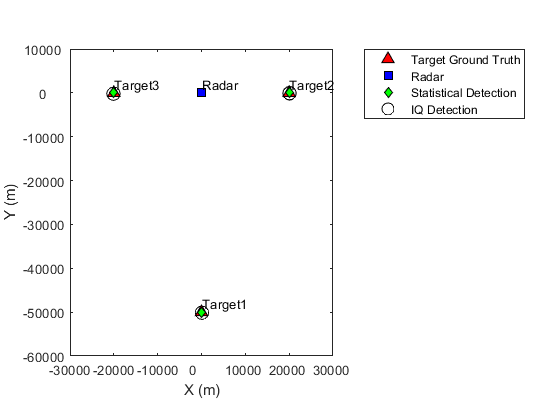

simTime = 0;
detBuffer_iq = {};
n = 0;

while true
    n=n+1;
    [sig, config] = sensor_iq([tgt1 tgt2 tgt3], simTime);
    if config.IsScanDone
        break;
    end
 
    % Processing
    [sigp,Gmf] = mf(sig);
    sigp = tvg(sigp);
    
    th = sqrt(threshold*db2pow(Gmf));
    ind = abs(sigp)>th;
    if any(ind)
        [~,idx] = max(abs(sigp));
         rng_est = rgates(idx);
        meas_sensor = [0;0;rng_est];
        meas_body = local2globalcoord(meas_sensor,'sr',...
            config.OriginPosition,config.Orientation);
        dets_iq = struct('Time',simTime,'Measurement',meas_body);
        detBuffer_iq = [detBuffer_iq;dets_iq]; %#ok<AGROW>
        rxsig(:,n) = sigp;  %#ok<AGROW>
    end
 
    simTime = simTime+1/updaterate;
end

iqdetpos = zeros(numel(detBuffer_iq),3);
for m = 1:numel(detBuffer)
    iqdetpos(m,:) = detBuffer_iq{m}.Measurement.';
end
iqdet = detectionPlotter(tp,'DisplayName','IQ Detection',...
    'Marker','o','MarkerSize',10,'MarkerEdgeColor','k');
plotDetection(iqdet,iqdetpos)

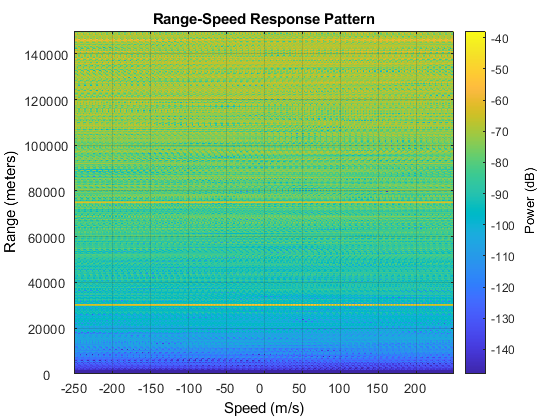

rangedoppler = phased.RangeDopplerResponse(...
    'RangeMethod','Matched Filter',...
    'PropagationSpeed',c,...
    'DopplerOutput','Speed','OperatingFrequency',fc);
plotResponse(rangedoppler,rxsig,coeff)

The plot above clearly indicates that the reuslt obtained from IQ signal generation is similar to the result generated from the statistical model.

## Summary

In this example, we will built a statistical model to generate detections based on the radar equation. We then created the equivalent IQ signal level model for the same scenario and compare the results. This workflow is a very convenient way to get a signal level model up and running quickly. Once the basic signal model is in place, it can be extended as the project dictates.

*Copyright 2020 The MathWorks, Inc.*